% Date and time: 1/5/2021 16:22
% Ahmad Alsayed
% process the 3D scans data form webots
% match 2D and 3D then generate and estimate 3D volume

clear
% load('simulation data\PC_3D_all_1.mat') %from the simulaiton
% load('simulation data\gps_imu.mat')



## save scans

 number_of_scan = 7700;   %  each sec 31.3 scans

% take only the horizontal layer from the 3D scan data
scan=cell(1,number_of_scan);
layer_id = 4; % r is the layer from 0 bottom to top 5
a = 1+512*layer_id ; b = 512+512*layer_id ; % only the horizontal layer
for i = 1:number_of_scan
    scan{i} = [scan_all{i}(a:b,2) -scan_all{i}(a:b,4)];
end

tic

robot_pose = cell(1,number_of_scan);
robot_pose_x(1:number_of_scan) = NaN;
robot_pose_y = robot_pose_x;
robot_pose{1} = [0;0];

robot_pose_x(1) = robot_pose{1}(1,1);
robot_pose_y(1) = robot_pose{1}(2,1);
count = 1;

%for i=1:100:number_of_scan-99

R = cell(1,30);
t = cell(1,30);
err_all_scans = cell(1,30);
err_final_scans = zeros(2,30);

map_r= cell(1,30);

scan_first = 350 ;
scan_n = scan_first;
iteration_count = 0;
map_r{1} =scan{scan_n}';

jj = 200; % every (jj)(100) scans
for i=(scan_n+jj):jj:number_of_scan
    Q = scan{i-jj}';
    P = scan{i}';
    
    icp_inputs.Q =Q; icp_inputs.P =P;
    icp_inputs.R =R; icp_inputs.t =t;
    icp_inputs.robot_pose =robot_pose;
    icp_inputs.map_r = map_r;
    icp_inputs.robot_pose_x = robot_pose_x;
    icp_inputs.robot_pose_y = robot_pose_y;
    icp_inputs.iteration_count = iteration_count;
    
    icp_function_2d_3d(icp_inputs,count);
    
    count = count+1;
    if err > 100
        disp('high error')
        err
        break
    end
end
toc

Elapsed time is 82.106817 seconds.


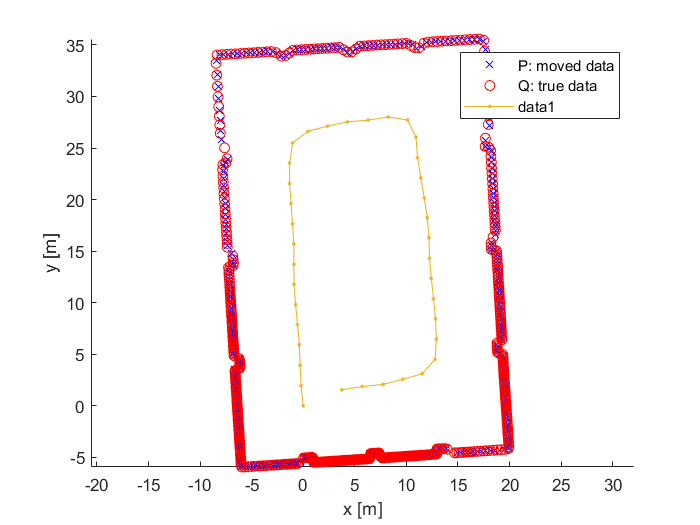

% map_r{5} = R{2}* map_r{4} + t{2};
% map_r{6} = R{1}* map_r{5} + t{1};

plot_data(map_r{count},map_r{count-1},'P: moved data','Q: true data')
hold on
plot(robot_pose_x,robot_pose_y,'Marker',".")
hold off

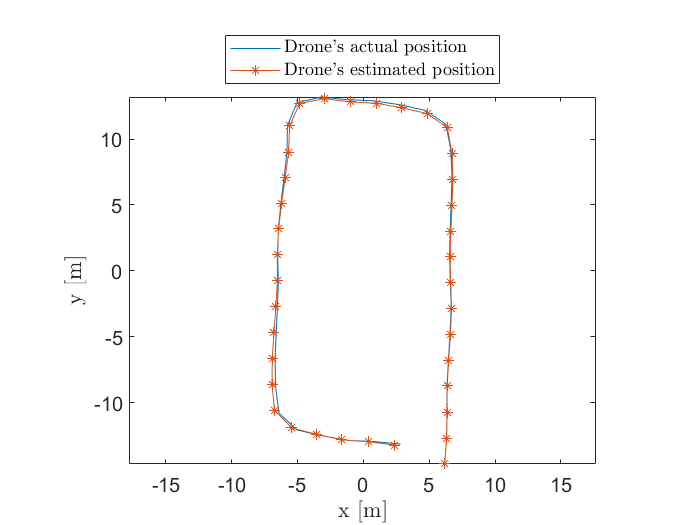

% actual Pose
xx = gps_imu_all(scan_first:jj:number_of_scan,2);
yy = gps_imu_all(scan_first:jj:number_of_scan,4);
plot(xx,-yy)
hold on

theta = pi-0.0323;
RR = [cos(theta) -sin(theta); sin(theta) cos(theta)];

xy = RR * [robot_pose_x;robot_pose_y];
xy = xy + [xx(1); yy(1)];
plot(xy(1,:),-xy(2,:),'Marker',"*")
hold off
axis equal
xlabel('x [m]','Interpreter','latex'); ylabel('y [m]','Interpreter','latex')
legend("Drone's actual position", "Drone's estimated position",'Location',"northoutside",'Interpreter','latex');
set(gca,'fontsize', 12)

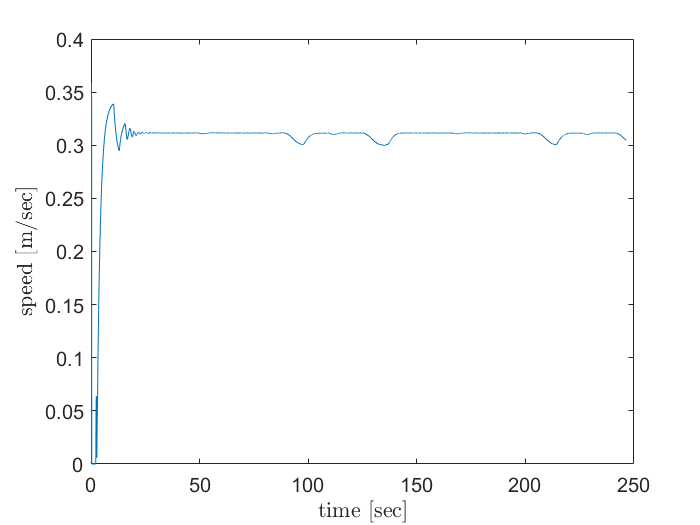

% flight speed

for i = 1:number_of_scan
    d_speed(i) = (sqrt( (gps_imu_all(i+1,4)-gps_imu_all(i,4))^2+...
        (gps_imu_all(i+1,2)-gps_imu_all(i,2))^2))/0.032;    
end
plot(gps_imu_all(1:7700,1),d_speed)
xlabel('time [sec]','Interpreter','latex'); ylabel('speed [m/sec]','Interpreter','latex')
set(gca,'fontsize', 12)

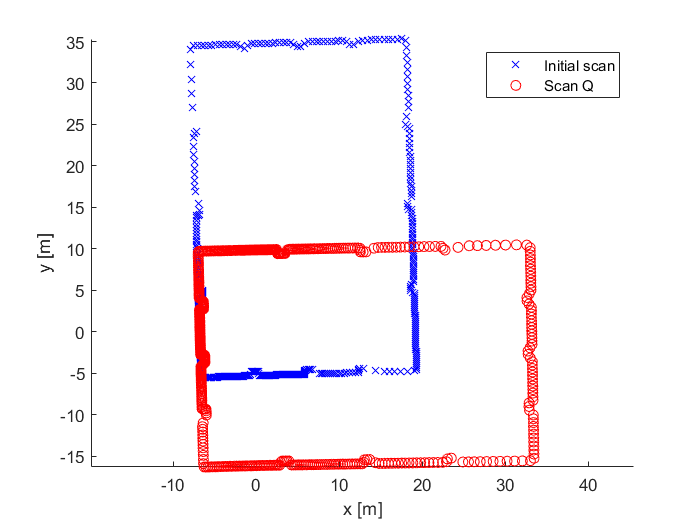

s1 = 37;
ss = 350+100*(s1-1);
plot_data(map_r{1},scan{ss}','Initial scan','Scan Q')

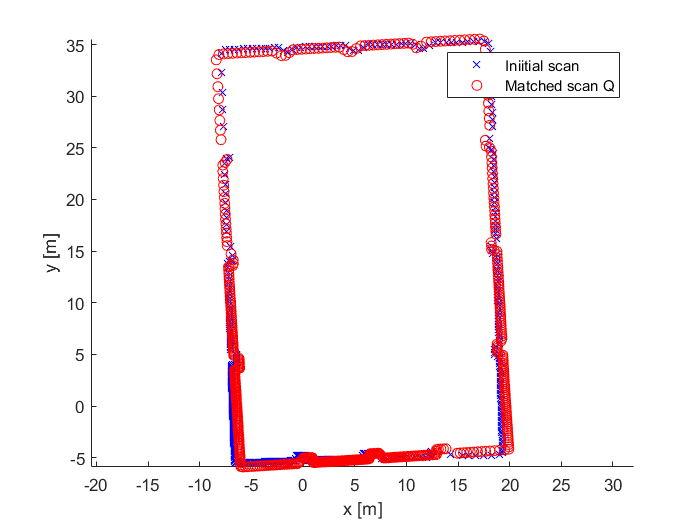

plot_data(map_r{1},map_r{s1},'Iniitial scan','Matched scan Q')
% hold on
% scatter(robot_pose_x(s1),robot_pose_y(s1),"d","filled")
hold off

map = occupancyMap(50,55,8);
 
pose_o = [20,15,0];
pose = [];
scan_n = scan_first;

pose(1,:) = pose_o + [robot_pose_x(1),robot_pose_y(1) ,0 ];

maxrange = 25;

x_oc = (scan{scan_n}(:,1))';
y_oc = (scan{scan_n}(:,2))';
scan_rotate = [x_oc; y_oc];
scan_rotate=scan_rotate(:,all(~isinf(scan_rotate)));
scan_rotate=scan_rotate(:,all(~isnan(scan_rotate)));
x_oc = (scan_rotate(1,:));
y_oc = (scan_rotate(2,:));
[theta,rho] = cart2pol(x_oc,y_oc);
scan_oc = lidarScan(rho,theta);
 
insertRay(map,pose(1,:),scan_oc,maxrange);
f1 = figure;
set(gcf,'Visible','on')
show(map)
hold on
plot(pose(:,1),pose(:,2),'b-o')
hold on
drawnow
%pause(0.1)
R_occ = [1 0; 0 1];
for i = 1:count-1
    scan_n = scan_n + jj;
    R_occ = R_occ * R{i};
    pose(i+1,:) = pose_o + [robot_pose_x(i+1),robot_pose_y(i+1) ,0 ];
    scan_rotate = R_occ*scan{scan_n}';
    scan_rotate=scan_rotate(:,all(~isinf(scan_rotate)));
    scan_rotate=scan_rotate(:,all(~isnan(scan_rotate)));
    x_oc = (scan_rotate(1,:));
    y_oc = (scan_rotate(2,:));
    [theta,rho] = cart2pol(x_oc,y_oc);
    scan_oc = lidarScan(rho,theta);
    insertRay(map,pose(i+1,:),scan_oc,maxrange);
    figure(f1);
    set(gcf,'Visible','on')
    show(map)
    hold on
    plot(pose(:,1),pose(:,2),'b-o')
    hold on
    drawnow
    %pause(0.1)
end

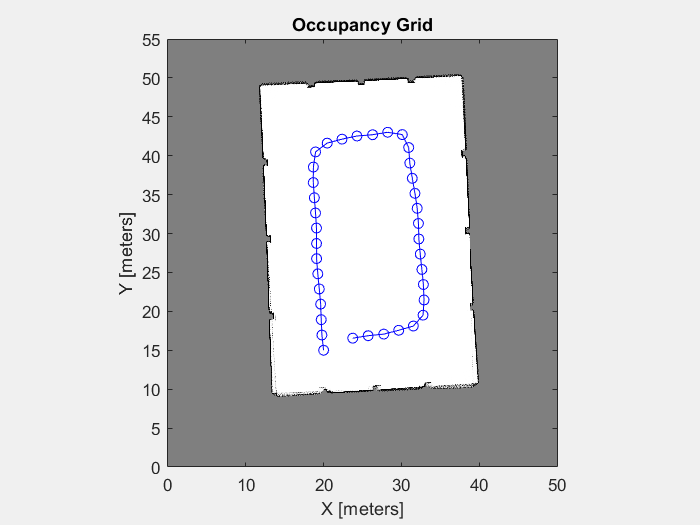

hold off

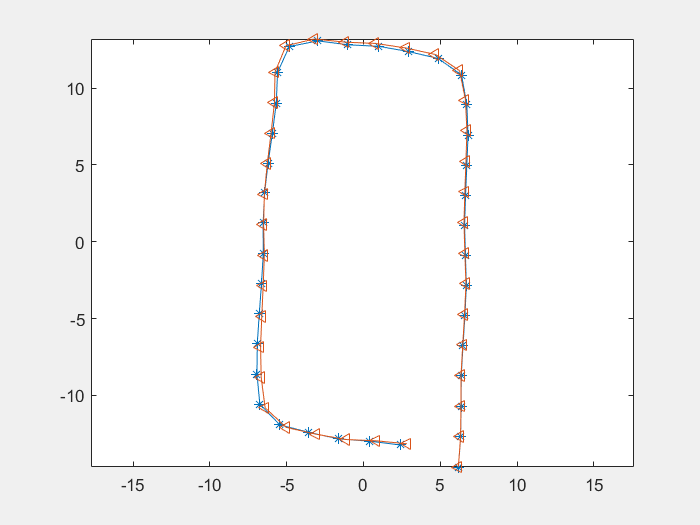

% Metrics
M.xy = [xy(1,1:size(xx,1));-xy(2,1:size(xx,1))];
M.xy_actual = [xx';-yy'];
plot(M.xy(1,:),M.xy(2,:),'Marker',"*")
hold on
plot(M.xy_actual(1,:),M.xy_actual(2,:),'Marker',"<")
hold off
axis equal


% sum of the squar error
E = 0;
for i = 1:size(xx,1)
    E = E + sqrt((M.xy(1,i)-M.xy_actual(1,i))^2+(M.xy(2,i)-M.xy_actual(2,i))^2 );
end
E

E = 8.3885

E/i

ans = 0.2267


sum(iteration_count)

ans = 714

sum(iteration_count)/size(xx,1)

ans = 19.2973

function plot_data(data_a,data_b,a,b)
    figure
    scatter(data_a(1, :),data_a(2, :),'blue','x')
%     hold on
%     plot(data_a(1, :),data_a(2, :),'--','HandleVisibility','off')
    hold on
    scatter(data_b(1, :),data_b(2, :),'red','o')
%     hold on
%     plot(data_b(1, :),data_b(2, :),'--','HandleVisibility','off')
    hold off
    xlabel('x [m]');ylabel('y [m]')
    legend(a, b); axis equal
end



